# Assignment 8 

# **Development of optimal smoothing to increase the estimation accuracy**  

By 

Group 19 

Ahmed Baza, Skoltech, 2020

Ahmed Elgohary, Skoltech, 2020

Mohammed Sayed, Skoltech, 2020

Ziad Baraka, Skoltech, 2020

**1)**The trajectory of a moving object is disturbed by normally distributed unbiased random acceleration 𝑎𝑖 with variance 𝜎𝑎2 = 0.22. All other conditions are the same as in Lab 5.Develop forward Kalman filter algorithm.

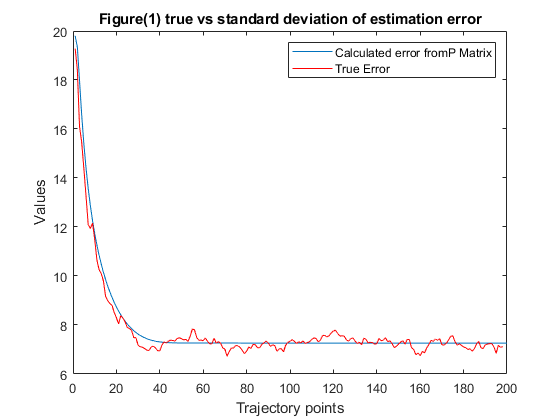

clear;
close all;
Err=zeros(500,200);      %  true error for trajectory
ErrV=zeros(500,200);    %  true error for velocity
Err_b=zeros(500,200);  % smoothed true error for trajectory
ErrV_b=zeros(500,200);  % smoothed true error for velocity

for m=1:500
T=1;                       % time interval between measurements 
a=normrnd(0,0.2,[200,1]);  % correlated random acceleration - data
    for i=2:200
    v(1)=1;
    v(i)=v(i-1)+a(i-1)*T;     % velocity data
    end
    v=v';
    for i=2:200
        X(1)=5;
        X(i)=X(i-1)+v(i-1)*T+((a(i-1)*T^2)/2);     % position true generated data
    end  
    X=X';
    eta = normrnd(0,20,[200,1]);      % correlated random noise - measurments
    for i=1:200
        Z(i)=X(i)+eta(i);         % measurements
    end
    Z=Z';

% Kalmn Filter 
N=200;
phi=[1 T;0 1];          % Transition Matrix
G=[T^2/2;T];            %Input Matrix 
H=[1 0]  ;              %observation Matrix
X0=[2;0];               %Initial condition of x
P=[10000 0;0 10000];   %Initial filtration error covariance matrix
R=20^2;                 %covariance matrix
sigma_a=0.2^2;         % variance of correlated noise
Q= G*G'*sigma_a;       % covariance matrix
K0=P*H'/(H*P*H'+R);      % kalmn filter constant
% Variable intialization
KK=zeros(N,2); % K values for the distance
PP=zeros(2,N);  % Covariance matrix
XX=zeros(1,N); % estimated values of kalmn filter for distance
Pi=zeros(N,1);
piv=zeros(N,1);
p_b={};   %filtration error covariance matrix
p_bi={};  % prediction error covariance matrix
XX_v=zeros(1,N);    %estimated values of kalmn filter for velocity
p=zeros(2,N);      % covariance matrix
for i=1:N
      
         X0= phi*X0;
         P=phi*P*phi'+Q;
         p_bi{i}=P;
         X0=X0+K0*(Z(i)- H*X0);
         XX_b(:,i)=X0;
         XX(i)=X0(1);
         XX_v(i)=X0(2);
         K=P*H'/(H*P*H'+R);
         KK(i,:)=K';
         P=(eye(2)-(K*H))*(P);
         Pi(i)=sqrt(P(1,1));
         piv(i)=sqrt(P(2,2));
         p_b{i}=P;
         K0=K;
         P=P;
         Err(m,i)=(X0(1)-X(i))^2;
         ErrV(m,i)=(X0(2)-v(i))^2;
end

    %Backward smoothing
      XXX_b=zeros(N,1);     % smoothed values of the  distance
      VV_b=zeros(N,1);      % smoothed values of the  velocity
      Pi_b=zeros(N-1,1);    % covarance matrix for distance
      PiV_b=zeros(N-1,1);   % covarance matrix for velocicty
      P=p_b{end-1};         % intialization of covariance matrix
  for i=N-1:-1:1
      A= (p_b{i})*(phi')/(p_bi{i+1});
      XX_b(:,i) =XX_b(:,i)+A*(XX_b(:,i+1)-phi*XX_b(:,i));
      P=p_b{i}+ A*(P-(p_bi{i+1}))*A';
      Pi_b(i)=sqrt(P(1,1));
      PiV_b(i)=sqrt(P(2,2));
      XXX_b(i)=XX_b(1);      % estimation values of x using smoothing
      VV_b(i)=XX_b(2);       % estimation values of V using smoothing
      Err_b(m,i)=(XX_b(1,i)-X(i))^2;   % True estimation error in distance
      ErrV_b(m,i)=(XX_b(2,i)-v(i))^2;  % True estimation error in velocity
  end 
  
end

ErrAvg=zeros(1,N-2);
for i=1:N-2
    ErrAvg(i)=sqrt((1/(m-1))*sum(Err(:,i+2)));   
end

ErrAvgV=zeros(1,N-2);
for i=1:N-2
    ErrAvgV(i)=sqrt((1/(m-1))*sum(ErrV(:,i+2)));   
end

ErrAvg_b=zeros(1,N-1);
for i=1:N-1
    ErrAvg_b(i)=sqrt((1/(m-1))*sum(Err_b(:,i+1)));   
end

ErrAvgV_b=zeros(1,N-1);
for i=1:N-1
    ErrAvgV_b(i)=sqrt((1/(m-1))*sum(ErrV_b(:,i)));  
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 
figure(1)  % the calculated estimation error with true estimation error 
plot(Pi)
 hold on
plot( ErrAvg,'r')

title('Figure(1) true vs standard deviation of estimation error')
xlabel('Trajectory points')
ylabel('Values')
legend('Calculated error fromP Matrix','True Error')

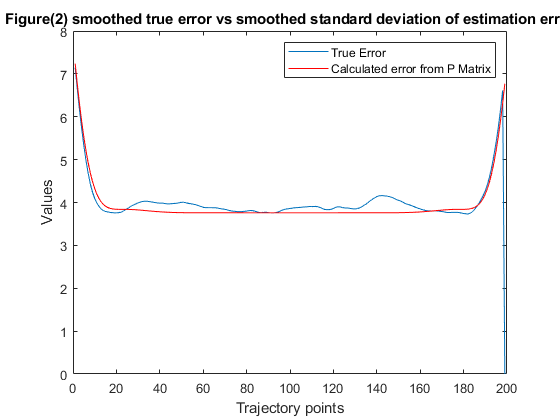

% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure(2)    
plot(1:N-1, ErrAvg_b)
hold on
plot(  Pi_b,'r')
title('Figure(2) smoothed true error vs smoothed standard deviation of estimation error')
xlabel('Trajectory points')
ylabel('Values')
legend('True Error','Calculated error from P Matrix')

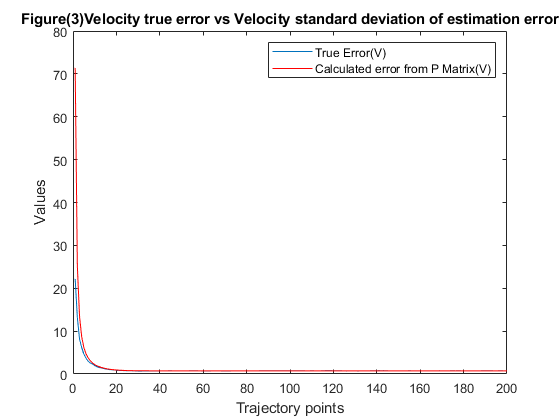

% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure(3)   
plot(ErrAvgV)
 hold on
plot( piv,'r')
title('Figure(3)Velocity true error vs Velocity standard deviation of estimation error')
xlabel('Trajectory points')
ylabel('Values')
legend('True Error(V)','Calculated error from P Matrix(V)')

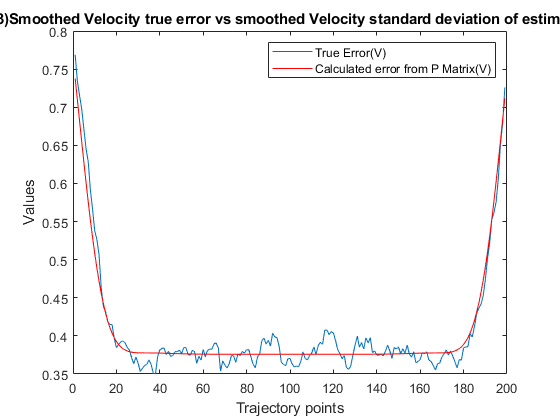


% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure(4)  
plot( 1:N-1, ErrAvgV_b)
 hold on
plot( PiV_b,'r')
title('Figure(3)Smoothed Velocity true error vs smoothed Velocity standard deviation of estimation error')
xlabel('Trajectory points')
ylabel('Values')
legend('True Error(V)','Calculated error from P Matrix(V)')

# **Learning Log:**